# Fehlerfortpflanzung

Wir betrachten die (sehr einfache) skalare Differentialgleichung

   
$$y'(t)=\lambda y(t) +g(t), ~~t \in [0,T],~~g(t):=-sin(t)-\lambda \cos(t)$$


mit Anfangsbedingung $y(0)=1$ und einem Parameter $\lambda\in\mathbb{R}$. Man rechnet einfach nach, dass (für jedes $\lambda$) $y(t)=\cos(t)$ die Lösung dieses Problems ist.

Wir wenden das Euler-Verfahren und die Trapezmethode auf dieses Problem an.

T=8;
lambda=0.5;
method= {'Euler-Verfahren','Trapezmethode'};
format short;
Endzeitpunkt=T

Endzeitpunkt = 8

lambda

lambda = 0.5000

exakt=cos(T);
ystart=1;

Für die (äquidistante) Schrittweite $h$ wählen wir $h=h_k=2^{-1-k}$, $k=1,\ldots,8$ (ggf. mit einer kleinen Korrektur, so dass  $T/h \in \mathbb{N}$ gilt). Sei $n$ so, dass $nh=T$ gilt. 

Für $k=1,\ldots,8$ wird der absolute Fehler im berechneten Ergebnis zum Endzeitpunkt $T$, d.h. $|y^n-y(T)|$, gezeigt.

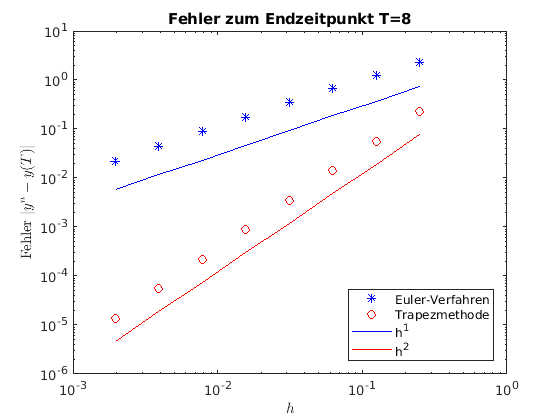

hh= zeros(1,8); errEuler= hh; errTrapez= hh;
for k=1:8
    h=2^(-1-k); n=round(T/h); h=T/n; % nun gilt n=hT.
    yalt_E= ystart;    yalt_T= ystart;
    for j=0:n-1
        % Euler-Verfahren
        yneu_E= yalt_E + h*(lambda*yalt_E + g(j*h,lambda));
        % Trapezmethode
        yneu_T= (yalt_T + 0.5*h*(lambda*yalt_T + g(j*h,lambda) + g((j+1)*h,lambda)))/(1-0.5*h*lambda);
        % Variablenshift
        yalt_E= yneu_E;    yalt_T= yneu_T;
    end
    hh(k)= h;
    errEuler(k)=  abs(exakt - yneu_E);
    errTrapez(k)= abs(exakt - yneu_T);
end
% Fehlerplot
plotError( hh, [errEuler; errTrapez], T, method);

# Aktivität:

 Variieren Sie $\lambda$ und $T$ systematisch. Zum Beispiel:

 $\lambda=0.5$,  $T\in \{1,2,4,8,16\}$,

$\lambda=-0.5$,  $T\in \{1,2,4,8,16\}$.

$\lambda=-20$,  $T\in \{1,2,4,8,16\}$.

Erklären Sie das beobachtete Fehlerverhalten für beide Methoden, insbesondere die Abhängigkeit des Fehlers von der Schrittweite $h$ und vom Endzeitpunkt $T$.

function gout= g(t,lambda) % Funktion wertet die Funktion g in der DGLn aus.
    gout= -sin(t) - lambda*cos(t);
end

function plotError( hh, error, T, method) 
% Fehlerplot
clf
loglog(hh,error(1,:),'b*', hh,error(2,:),'ro');
hold on;
scale= error(:,1)/3;
hs= hh(1);
loglog(hh,scale(1)*(hh/hs),'b-', hh,scale(2)*(hh/hs).^2,'r-');
title( ['Fehler zum Endzeitpunkt T=',num2str(T)]);
legend(method{1}, method{2}, 'h^1', 'h^2', 'Location','southeast');
xlabel('$h$','Interpreter','latex'); ylabel('Fehler $|y^n-y(T)|$','Interpreter','latex');
hold off;
end
